# Homework 2

## Problem 2-1

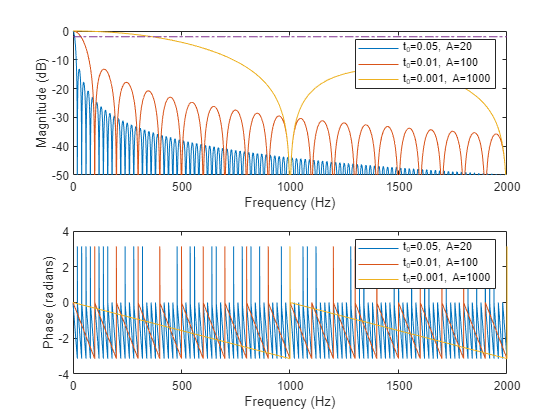


% Setting up parameters
f = 0:0.01:2000; % Small frequency spacing for sufficient resolution on case 1
t0_1 = 0.05; t0_2 = 0.01; t0_3 = 0.001;
A_1 = 20; A_2 = 100; A_3 = 1000;

% Setting up function of X(j2pif):
X = @(t0,A) A*(1-cos(2*pi.*f*t0)+1j*sin(2*pi.*f*t0))./(1j*2*pi.*f);

X_1 = X(t0_1, A_1); mag_X_1 = 20*log10(abs(X_1)); ang_X_1 = angle(X_1);
X_2 = X(t0_2, A_2); mag_X_2 = 20*log10(abs(X_2)); ang_X_2 = angle(X_2);
X_3 = X(t0_3, A_3); mag_X_3 = 20*log10(abs(X_3)); ang_X_3 = angle(X_3);

bandwidth_estimate = abs(X_1(2))-3; % Units in dB
% Can use any equation since X_1(2)=X_2(2)=X_3(2), using index 2 term since f=0 is undefined
bandwidth_estimate = repmat(bandwidth_estimate, [1,length(f)]);

% Magnitude plots
subplot(2,1,1);
plot(f,mag_X_1,f,mag_X_2,f,mag_X_3, f, bandwidth_estimate, '-.');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
ylim([-50 0]);
legend('t_0=0.05, A=20', 't_0=0.01, A=100', 't_0=0.001, A=1000');

% Phase plots (2-1e)
subplot(2,1,2);
plot(f,ang_X_1,f,ang_X_2,f,ang_X_3);
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
legend('t_0=0.05, A=20', 't_0=0.01, A=100', 't_0=0.001, A=1000');

(2-1d) For (i), the frequency is 7.31 Hz. For (ii), the frequency is 36.56 Hz. For (iii), the frequency is 365.4 Hz.

(2-1e) A linear phase component is present due to the arctan(sin/(cos+1) ) term. The gradient is different in each case due to the decreasing t_0 term, which decreases the rate at which the 2*pi*f*t_0 term changes. The jumps of pi radians in the phase spectra are caused by the limits of the limits of the arctan component of the phase equation (see 2-1b). 

## Problem 2-4

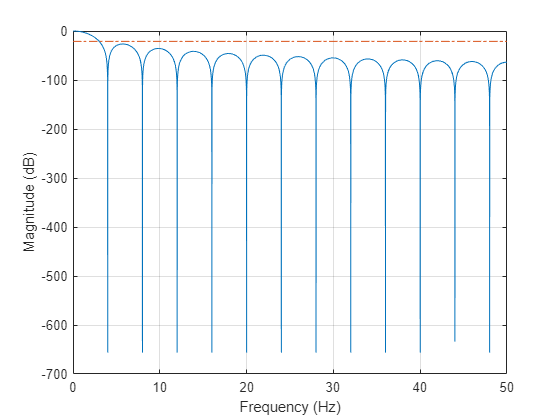

f = 0:0.01:50;

% Using T = 1
W = (1/8)*(sin(pi.*f*1/4)./(pi.*f*1/4)).^2; % Using sin(x)/x for sinc function
W_0 = 1/8; % sinc(0) = 1

bandwidth_estimate = 20*log10(abs(W_0))-3; % Units in dB
bandwidth_estimate = repmat(bandwidth_estimate, [1,length(f)]);

mag_W_ref = 20*log10(abs(W)/abs(W_0));


figure;
plot(f, mag_W_ref, f, bandwidth_estimate, '-.');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

(2-4d) The frequency location of the 3 dB down point is 3 Hz. The amplitude of the highest sidelobe is -26.52 dB and its location is 5.69 Hz. The first zero crossing is located at 4 Hz. The dominant roll-off rate is 11 dB/octave at higher frequencies.

(2-4e) The high frequency roll-off of this window is higher than that of the rectangular window (11 dB for this window vs 6 dB for rectangular) but less than that of the Hann window (11 dB vs 18 dB for the Hann window).

## Problem 2-5

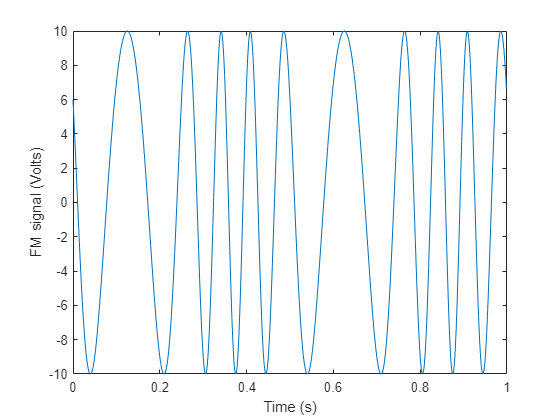

% Problem 2-5a
fs = 75 * 10; % Sampling frequency is 10 times highest value of instantaneous frequency, 75 Hz
dt = 1/fs;
t = 0:dt:1-dt;



phi = @(t, f_m, gam) (gam*f_c/f_m)*cos(2*pi*f_m.*t);

y = @(t, f_m, gam) A*sin(2*pi*f_c.*t + phi(t, f_m, gam));
f = @(t, f_m, gam) f_c + (1/(2*pi))*(-gam*f_c*2*pi*sin(2*pi*f_m.*t));

A = 10; f_c = 10; f_m = 2; gam = 0.5;

y_a = y(t, f_m, gam);
f_a = f(t, f_m, gam);

figure;
plot(t, y_a);
xlabel('Time (s)');
ylabel('FM signal (Volts)')

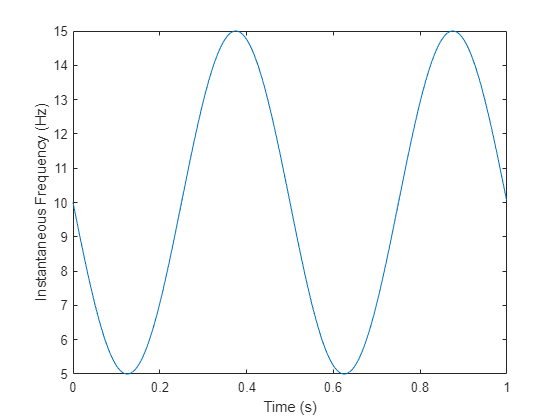


figure;
plot(t, f_a);
xlabel('Time (s)');
ylabel('Instantaneous Frequency (Hz)')

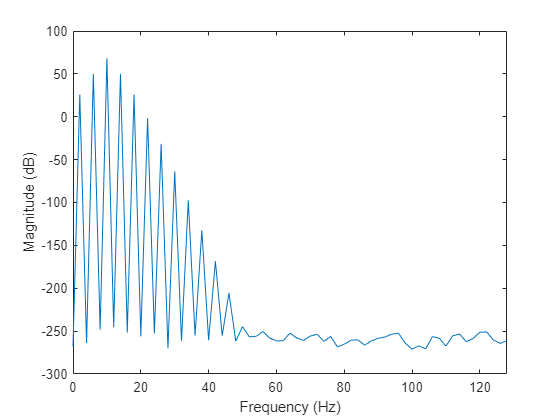


% Problem 2-5b
fs = 1024; % 1024 samples a second
dt = 1/fs;

% Part (i)
t_1 = 0:dt:0.5-dt;
f_m = 4; gam = 0.1;

fft_plotter(t_1, f_m, gam, fs);

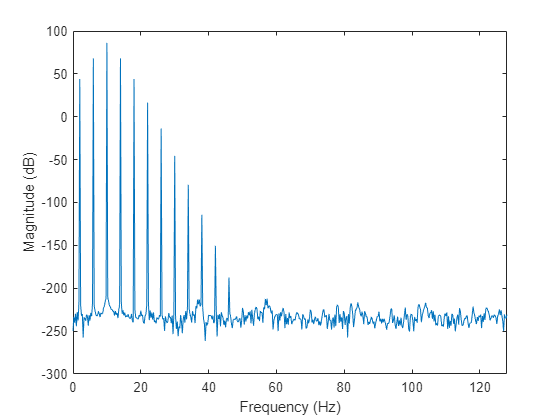


t_2 = 0:dt:4-dt; t_3 = t_2; t_4 = t_2;

% Part(ii)
f_m= 4; gam = 0.1;
fft_plotter(t_2, f_m, gam, fs);

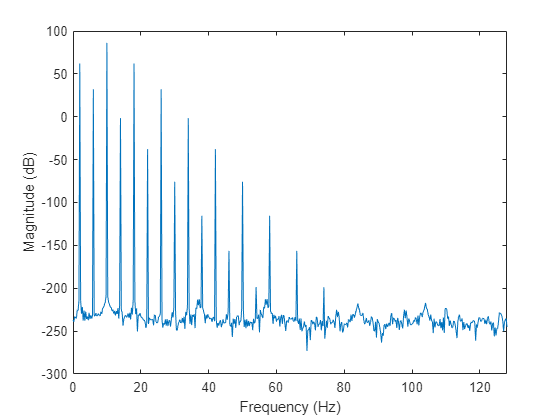


% Part (iii)
f_m = 8; gam = 0.1;
fft_plotter(t_3, f_m, gam, fs);

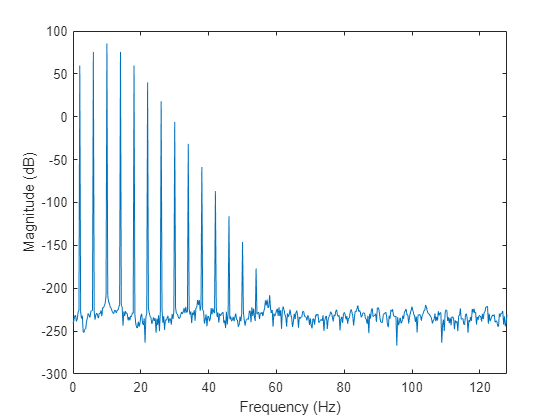


% Part(iv)
f_m = 4; gam= 0.25;
fft_plotter(t_4, f_m, gam, fs);

A longer signal duration (comparing (i) and (ii)) leads to "sharper" peaks in the amplitude density spectrum. Increasing f_m (comparing (ii) and (iii)) decreases the amplitude density spectrum peak at every other peak. Increasing gamma (comparing (ii) and (iv)) increases the "width" of the spectrum.

function [f, P] = fft_plotter(t, f_m, gam, fs)
A = 10; f_c = 10;

phi = @(t, f_m, gam) (gam*f_c/f_m)*cos(2*pi*f_m.*t);
y_func = @(t, f_m, gam) A*sin(2*pi*f_c.*t + phi(t, f_m, gam));

y = y_func(t, f_m, gam);
Y = fft(y);
N = length(Y);
k = 0:(N-1)/2;
f = k.*fs/N;
P = Y(1:N/2);

figure;
plot(f, 20*log10(abs(P)));
xlim([0, 128]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
end